clc;   clear;   close all ;

load('QandReye_noDisturbance.mat')		
% list_factory = fieldnames(get(groot,'factory'));
% index_interpreter = find(contains(list_factory,'Interpreter'));
% for i = 1:length(index_interpreter)
%     default_name = strrep(list_factory{index_interpreter(i)},'factory','default');
%     set(groot, default_name,'latex');
% end

## Load data


close all ;

ym1 = data{396}.Values.Data(:,1);
ym2 = data{396}.Values.Data(:,2);

y1 = data{365}.Values.Data(:,1);
y2 = data{365}.Values.Data(:,2);

disturbance = data{397}.Values.Data(:);

N = length(ym1);
final = 50000;
step = final/N;

t_sec = 0 : step : final-step;
t_hour = t_sec/3600;

## Plot output 1 - T_air

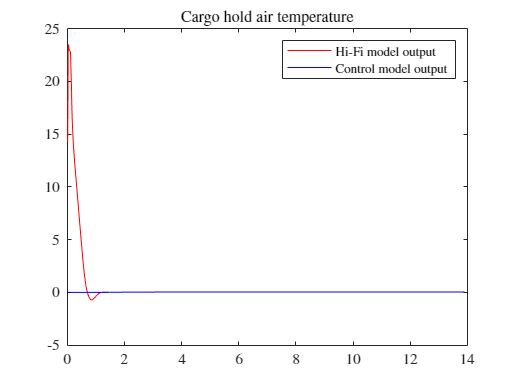

figure(1)
plot(t_hour,ym1,'r')
hold on
plot(t_hour,y1,'b')
hold off
title("Cargo hold air temperature")
legend("Hi-Fi model output", "Control model output")

## Plot output 2 - Superheat

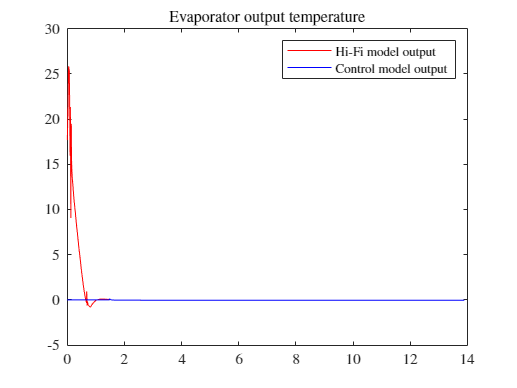

figure(2)
plot(t_hour,ym2,'r')
hold on
plot(t_hour,y2,'b')
hold off
title("Evaporator output temperature")
legend("Hi-Fi model output", "Control model output")

## Plot